# Reaction Analyzer

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

In this script, you will design an experiment to measure the reaction time using several LEDs and push buttons. The data from those experiments will be post-processed using MATLAB. 

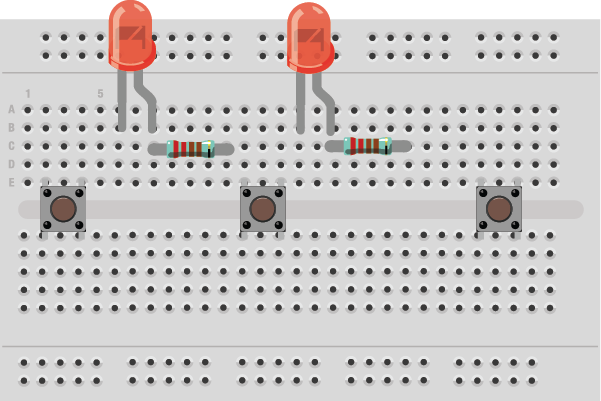

This image was created using [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

**Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

In this interactive course, you will learn how to use Arduino technology to measure and analyze your reaction times. Working with LEDs and buttons will give you hands-on experience in accurately measuring your reaction time. Furthermore, you will have the opportunity to compare the reaction times of your dominant and non-dominant hands, providing valuable insights into the influence of hand dominance on your reaction speed. Get ready to dive into the captivating world of reaction analysis and discover the fascinating aspects of your own reflexes!

## Measuring reaction time

### Wiring diagram

In this part of the script, we are starting to use a push button to gather user feedback. The Arduino board will be used to measure the user's reaction time. As a first step, we will wire a simple circuit with one LED and one push button. The Simulink model provided will be used to turn on the LED randomly, and the button will be pushed to turn off the LED. The time the user takes to make the button after the LED turns on is considered the reaction time. 

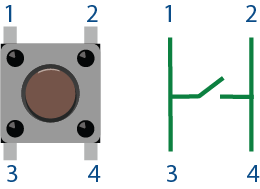

Figure 1 - Four leg push button diagram - this image was created using [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

In Figure 1, we show how the push button functions. It is important to note that your push button might differ slightly from the one presented here. This button is a **normally open** button, meaning the circuit is open when it is released in its normal state. Pushing the button closes the circuit, creating a connection between the right and left sides of the button. Another push button could be normally closed or make a connection between the top and bottom pins. You should check your button's specs before continuing and adapt the rest of this script if you use a different button.

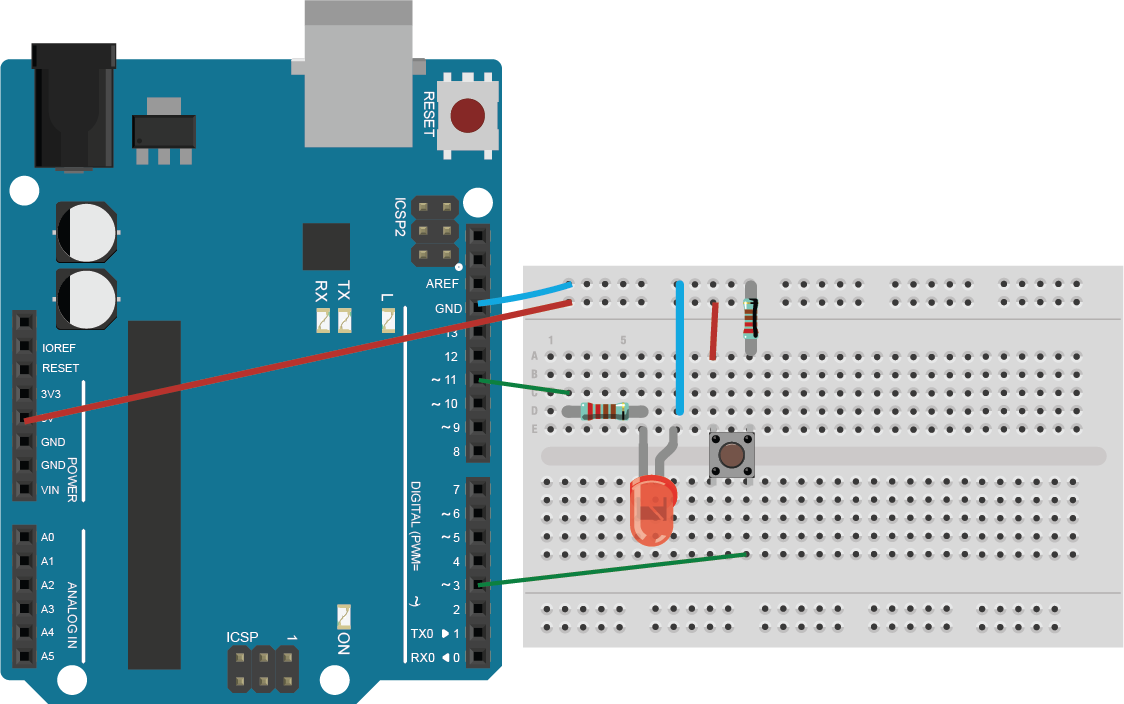

Figure 2 - Wiring diagram one button - this image was created using [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

#### How does the button work?

 **Exercise. **Based on the Figures 1 and 2, what should be the voltage at the analog pin read from the button when the button is UNPUSHED?

Exercise1(0)

 **Exercise. **Based on the two previous figures, what should be the voltage at the analog pin read from the button when the button is PUSHED?

Exercise2(0)

 **Exercise. **Select the board and pins that you are currently using.

MyBoard = "Arduino Uno";
MyLEDPin = "";
MyButtonPin = "";

  **Try. **Open the `OneButtonTest.slx` to test your wiring. The pin number associated with the LED and Button should be set to the correct value.

 
SetButtonModel(MyBoard,MyLEDPin,MyButtonPin);

 **Pro-tip.** The wiring is correct if the scope changes from 0 to 1 when the button is pushed. If your LED is not turning on, it is potentially because the polarity of the LED is reversed. For more details on how to wire an LED, please refer to [BlinkToSOS.mlx](matlab:open('./BlinkToSOS.mlx')).

  **Try. ** Click **Run with IO **in the Simulink toolstrip and observe the LED and scope when pushing the button. 

### Two button experiment

In the previous section, we learned how to use push buttons. In this section, we will design an experiment with two button to explore the following hypothesis:

**        "The reaction time in one's dominant hand is faster than in a non-dominant hand."**

The reaction time will be measured using two buttons and two LEDs. The experiment will go as follows:

- One of the LEDs will turn on randomly.

- The user must push the corresponding button (left or right) to turn off the LED.

- The reaction time is considered to be the time taken to turn off the LED.

- This reaction time will be registered and transmitted to the computer through USB connection for analysis.

#### Wiring

 **Exercise. **Based on the wiring from the previous section, wire a second button and LED to your Arduino. When done, use the following button to show the correct wiring diagram.

ShowWiringTwoButton(Enable = false,HighlightWiring = false,ExternalFigure = false)

In Figure 3, the blue wire represents the ground (GND), the red wire represents the board voltage (either 3.3 or 5V, depending on the board), and the green wire means the connection to the digital pins.

We provide an updated Simulink model called [`TwoButtonReaction.slx`](matlab:open('../Models/TwoButtonReaction.slx'))` to gather the reaction time using two buttons.`

  **Try. **Open the model and modify the pin number accordingly.

 

% Open the model:
open(fullfile("Models","TwoButtonReaction.slx"))

% Programmatically set the board:
Mdl = load_system(fullfile("Models","TwoButtonReaction")); 
set_param(Mdl,"HardwareBoard", MyBoard); 

#### Gather Data

Now that you have prepared the model to run on the Arduino board, it is time to deploy it and gather reaction time data using your Arduino.

  **Try. **Deploy the model to your Arduino by clicking the **Build, Deploy & Start **button in the Simulink toolstrip (**HARDWARE TAB**)

The data is gathered through a serial port connection: every time the hardware collects a reaction time, it is communicated through the Arduino USB board. This module contains an app that can monitor the data sent by your Arduino through the USB port.

  **Try. **Open the app.

 
evalc("SerialMonitor"); % App is opened using evalc to avoid screenshot of the app to appear in script.

Now that we have deployed the model to your Arduino hardware and opened the app, we can start gathering the reaction time. 

  **Try. **Gather reaction time following these steps:

- Select the **COM port** corresponding to your Arduino Hardware.

- Click **Connect**.

- Click **Start/Stop**.

- Push both buttons at the same time to turn them off.

- Please turn off the LED by pushing the button every time it turns on.

- *( Repeat many times )*

- When enough reaction time is measured, click **Start/Stop **again.

- Click **Export Data **to save the reaction time in a mat file.

## Lab report

In this section of the scripts, you will explore processing real-world data you just gathered using your Arduino. You will learn how to pre-process, visualize, and analyze the data. For those of you who did not collect reliable data or decided to skip the previous section, we are providing our reaction data in `Data/ReactionTwoButton.mat`.

### Pre-processing raw data

Pre-processing data is a crucial step in data analysis as it helps ensure the information's accuracy, reliability, and relevance. By removing outliers, handling missing values, normalizing data, and addressing other data quality issues, you will obtain more meaningful results and make informed decisions based on reliable data. Before getting started, you should load the data that you have gathered through your Arduino. If you cannot acquire reliable data, we are also providing results from our own experiment in `Data/ReactionTwoButton.mat`.

 **Exercise. **Select the data you want to use to perform the data analysis.

load("Data/ReactionTwoButton.mat","SerialData")

% Check that the data loaded is from your arduino
if exist("SerialData","var") == 1
    disp("Good job! You loaded data gathered from the Arduino board.")
    SerialData
else
    warning("The data you loaded does not include serialdata gathered from your Arduino.")
end

Good job! You loaded data gathered from the Arduino board.


SerialData = 2000×1 timetable
       Time        Data  
    __________    _______

    1 sec         -322.32
    2 sec          242.47
    5 sec          -333.5
    6.2591 sec    -222.15
    8.6427 sec    -241.07
    10.779 sec     320.16
    11.999 sec    -301.24
    13.763 sec    -249.01
    15.128 sec     327.24
    18.128 sec    -221.77
    19.448 sec     -726.2
    21.586 sec     222.12
    24.586 sec    -222.13
    26.81 sec      222.76
    28.213 sec    -221.72
    31.213 sec     269.47


The SerialData variable that was just loaded is a table containing two vectors:

- Data: correspond to the reaction time that was gathered using the Arduino. Positive reaction time corresponds to a reaction time from the right button, and negative reaction time correspon to a reaction time collected from the left button.

- Time: correspond to the time at which the reaction time was collected.

The value column represents the reaction time gathered from the Arduino in milliseconds. The value is positive if the reaction time if it is the right LED reaction and negative if it is the left side reaction time. To make the table more readable, we should add a column with "left" and "right" and only keep the absolute value of the value column.

   If you are unfamiliar with using MATLAB Table, vector and logical indexing, consider completing [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a 2-hours training

  **Try.** Create a logical vector with value `true` if the data was gathered from the left button and `false `otherwise.

 IsRight = SerialData.Data > 0;

 **Exercise.** Select the right operator to define the logical vector with `true` value if the data was gathered from the left button and `false `otherwise.

IsLeft = SerialData.Data == 0;

% Check Answer:
IsLeft = CheckIsLeft(IsLeft,SerialData);

Now that we have identified which reaction time are from the right or left hand, we can add a column to the table storing this information. With this extra column, the sign of the reaction time becomes redundant and can be omitted. This increases the readability of the data. 

  **Try. **Create a column "`Side" `indicating 

 

if ~isempty(IsLeft) % Check that the IsLeft vector was defined correctly
    SerialData.Side(IsRight) = "Right"; % Add column with "Left" and "Right" based on the vector
    SerialData.Side(IsLeft) = "Left";   % defined previously
    SerialData.Side = categorical(SerialData.Side); % Turn the "Left" and "Right" into categorical
    SerialData % Display the table
end

In the previous code, we are transforming the Side column as a [categorical](https://www.mathworks.com/help/matlab/categorical-arrays.html) datatype. Categorical data types are used to store data with values from a finite set of discrete categories. In our case, because the side can only be "Left" or "Right", using categorical enables better performance and less memory usage than if we were using [string](https://www.mathworks.com/help/matlab/characters-and-strings.html) datatype.

Now that we created a `Side` column in the SerialData timetable, we do not need to keep the sign in the `Data column. `

  **Try.** Run this code to keep the absolute value of the reaction time.

SerialData.Data = abs(SerialData.Data) % Keep absolute value of the reaction time

Before ro proceed with a formal data analysis, we should create some quick data visualization.

  **Try.** Select the Side to visualize the histogram of reaction time.

Side = "None";

switch (Side)
    case "Right"
        figure
        histogram(SerialData.Data(SerialData.Side == Side),SeriesIndex=1)
        title("Reaction time on right hand")
        ylabel("Reaction time (ms)")
        xlabel("Count")
    case "Left"
        figure
        histogram(SerialData.Data(SerialData.Side == Side),SeriesIndex=2)
        title("Reaction time on left hand")
        ylabel("Reaction time (ms)")
        xlabel("Count")
end

### Data analysis

In this section, we will perform a simple statistical analysis of the data gathered using the Arduino board. 

#### Create box chart

A box chart (or box plot) displays statistical information (median, lower/upper quartiles, outliers) about the plotted data. They will help us compare the data from the right and left sides.

 **Exercise. **Use a **Create Plot** Live Task it to create a box chart over the `SerialData` with the **Side** as X-data and **Data** as Y-data

legend("off")

 **Exercise.** Modify the axis labels using the [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html?searchHighlight=xlabel&s_tid=srchtitle_support_results_1_xlabel) and [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html?searchHighlight=ylabel&s_tid=srchtitle_support_results_1_ylabel) function

% Add your code here:

% Check Answer:
CheckLabel(gca)

 **Exercise.**  Add a [`title`](https://www.mathworks.com/help/matlab/ref/title.html) to your figure.

% Add your code here:


The data presents a lot of outliers; you might want to change the limit of the y-axis to zoom on the box chart.

  **Try.** Modify the limit of the y-axis.

ylim([0,1600])

When you are satisfied with your figure, you might want to save or export it to your format of choice. The MATLAB `saveas` function allows you to export the figure to your preferred format.

  **Try.** Export the figure with your image format of choice

if exist("h","var") 
    filename = ""+".eps";
    if extractBefore(filename,".") == ""
        warning("Please complete the edit field above to specify the file name.")
    else
        filepath = fullfile(currentProject().RootFolder,"Images",filename);
        saveas(h,filepath);
    end
end

 ** Pro-tip. ** Formats such as (.eps), (.svg), and (.png) are the preferred way to export your figure as an image file. The (.fig) is a MATLAB format that allows you to reopen and modify your figure later.

#### Removing outlier

In the previous section, we represented the data using a box chart. This figure showed the presence of numerous outliers in the results gathered from the Arduino. The outliers are any data point over the box plot's maximum notch region. The maximum edge of this region is defined using the following formula, in which $m$ represents the median, $IQR$ is the interquartile range, and $n$ is the number of data points:

 
$$m+\frac{1.57\ IQR}{\sqrt n}$$


Gathering reactions can be a long process during which the participants might be inattentive. We are considering that every reaction time over one-second results from inattention. Moreover, we assume that inattention is not correlated with the participant's dominant arm. Therefore, we will remove these data points from the results.

 **Exercise.** Modify the **TimeLimit** to be 1 second (1000 ms) and the **operator** to remove the reaction time over 1 second.

TimeLimit = 2000;
IdxOutlier = SerialData.Data == TimeLimit;
NewTable = SerialData(~IdxOutlier,:);

% Visualize the out
figure
h = histogram(SerialData.Data,SeriesIndex=2,BinWidth=(TimeLimit-min(SerialData.Data))/8,BinLimits=[min(SerialData.Data) max(SerialData.Data)]);
hold on
histogram(NewTable.Data,SeriesIndex=1,BinWidth=(TimeLimit-min(SerialData.Data))/8,BinLimits=[min(SerialData.Data) max(SerialData.Data)]);
hold off
h.Parent.YAxis.Scale = "log";
xlim("tight")
xline(TimeLimit,"--")
legend("Removed datapoints","Remaining datapoints","Reaction Time limit")

  **Try. **Plot the remaining data points in a box plot.

 
h = PlotSerialData(NewTable);

  **Try.** Explore the mean, median, max, and min of the reaction time gathered.

if ismember("Side",NewTable.Properties.VariableNames)
    TableSummary = pivot(NewTable, Rows="Side", DataVariable="Data", Method="mean", RowLabelPlacement="rownames")
else
    warning("Serial data format is not formatted correctly, please follow all of the instructions.")
end

 **Reflect. **Is your reaction time better on your right or left hand? Does it correspond to your dominant hand? (The dataset included in the module was created by a right-handed person)

So far, we learned how to load and pre-process data. At this point, you might want to save the pre-processed data to use another time without going over the pre-processing steps again. The [`save`](https://www.mathworks.com/help/matlab/ref/save.html) command allows storing any variable from your workspace in a file. 

 **Exercise.** Save new data as a mat file

Filename = "";
if Filename ~= ""
    NameFileSave = fullfile("Data",Filename+".mat")
    save(NameFileSave,"NewSerialData")
else
    warning("Enter the file name you would like in the edit field above.")
end

### Export your work

In this section, we prepare this script to be exported as a text document such as a Word or PDF. Exporting your live scripts offers several advantages in terms of communicating your findings. In educational settings, they can generate your lab report directly. In contrast, they can be used in the industry to create reports that everybody in the company can read, not just MATLAB users.

 **Exercise.** Export this script as a report.

FileOut = fullfile(currentProject().RootFolder,"Scripts","ReactionAnalyzer.docx");
if isfile(FileOut)
    delete(FileOut)
end

export(fullfile(currentProject().RootFolder,"Scripts","ReactionAnalyzer.mlx"),FileOut,...
    OpenExportedFile=false,...
    HideCode=false);

## Conclusion

In this script, you learned how to interact with Arduino hardware using a button actively. Experiments were carried out to measure your reaction time. The final analysis compared the reaction time in your left and right hands to see if there is a correlation between your reaction and your dominant hand. Your conclusion should be described in the last part of this script, used as a lab report, and exported in your preferred format (Word document or PDF).

## Further exploration

If you want more data to validate the hypothesis, repeat the experiment with multiple people, or read about [published research on the topic](https://www.josam.org/josam/article/view/66#%3A~%3Atext%3DCollected%20data%20shows%20that%20the%2Creaction%20time%20is%20270%20msec.).

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Helper Functions

function Exercise1(answer)
    if  answer == 1
        disp("Good job! The voltage should be 0V.")
    else
        warning("Hint: leg 4 and 2 of the button are always connected. The button is"+...
            " connected to the Arduino through leg 4 which should have the same voltage as leg 2.")
    end
end

function Exercise2(answer)
    if  answer == 2
        disp("Good job! The voltage should be the board voltage (3.3 or 5V depending on your board.)")
    else
        warning("Hint: leg 4 and 2 of the button are always connected. The button is"+...
            " connected to the Arduino through leg 4 which should have the same voltage as leg 2.")
    end
end

function ShowWiringTwoButton(opts)
    arguments
        opts.Enable (1,1) logical = false;
        opts.HighlightWiring (1,1) logical = false;
        opts.ExternalFigure (1,1) logical = false;
    end

    % Load image:
    if opts.HighlightWiring 
        [Img,~,~] = imread(fullfile("Images","TwoButtonHighlight.png"));
    else
        [Img,~,~] = imread(fullfile("Images","TwoButton.png"));
    end

    % Display image:
    if opts.Enable

        imshow(Img)
        
        % Add figure caption:
        annotation("textbox",[0,0,1,0.05],...
        "String","Figure 3 - Wiring diagram one button (this image was created using fritzing-parts)",...
        "HorizontalAlignment","center","VerticalAlignment","bottom","LineStyle","none");

        % Display in external figure:
        if opts.ExternalFigure
            set(f,"Visible","on")
        end
    end
end

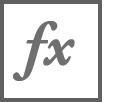`SetButtonModel`

function SetButtonModel(MyBoard,MyLEDPin,MyButtonPin)

    % Prepare pin:
    MyLEDPin = replace(MyLEDPin,"D","");
    MyButtonPin = replace(MyButtonPin,"D","");
    
    % Load model
    Mdl = load_system(fullfile("Models","OneButtonTest"));
        
    % Set Board:
    set_param(Mdl,"HardwareBoard", MyBoard)
    
    % Pre-set digital input pin    
    if MyButtonPin ~= ""
        set_param("OneButtonTest/Signal From Button","pinNumber",MyButtonPin)
    else
        warning("You needed to specify the pin used for the button in the previous section.")
    end
    
    % Pre-set digital output pin
    if MyLEDPin ~= ""
        set_param("OneButtonTest/Signal To LED","pinNumber",MyLEDPin)
    else
        warning("You needed to specify the pin used for the LED in the previous section.")
    end
    
    open_system("OneButtonTest")
end

`CheckPlotLiveTask`

function CheckPlotLiveTask(h)
    err = false;
    if string(class(h)) ~= "matlab.graphics.chart.primitive.BoxChart"
        err = true;
        warning("The plot should be a BoxChart.")
    end
    if string(h.Parent.Title.String) ~= "value vs. Side"
       err = true;
       warning("The X-axis data should be Side and value as Y-axis data")
    end
    if ~err
        disp("Good job! You created the plot correctly.")
    end
end

`CheckLabel`

function CheckLabel(ax)
    err = false;
    CurrentXLabel = string(ax.XLabel.String);
    CurrentYLabel = string(ax.YLabel.String);
    if CurrentXLabel == "value"
        err = true;
        warning("Please modify the x-axis label using xlabel.")
    end
    if CurrentYLabel == "Side"
        err = true;
        warning("Please modify the x-axis label using ylabel.")
    end
    if err
        warning("You could use 'Hand' and 'Reaction time (ms)' as new label.")
    else
        disp("Good job! You modified the axis labels correctly.")
    end
    
end

`PlotSerialData`

function h = PlotSerialData(SerialData)
    if ismember("Side",SerialData.Properties.VariableNames) 
        % Create boxchart of SerialData.Side and SerialData.Data
        h = boxchart(SerialData.Side,SerialData.Data,"DisplayName","Data");
        
        % Add xlabel, ylabel, title, and legend
        xlabel("Side")
        ylabel("Data")
        title("Data vs. Side")
        legend("off")
        xlabel("Hand")
        ylabel("Reation time (ms)")
        title("Experiment dominant hand")
    else
        warning("Serial data format is not formatted correctly, please follow all of the instructions.")
        h = [];
    end
end

`CheckIsLeft`

function IsLeft = CheckIsLeft(IsLeft,SerialData)
    % Check answer:
    if IsLeft == (SerialData.Data < 0 )
        disp("Good job! You defined the IsLeft vector correctly.")
    else
        warning("You picked the wrong operator, refer to the previous activity to select your logical operator correctly.")
        IsLeft = [];
    end
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Copyright 2023 The MathWorks™, Inc